# Test harness for CRCBPSO using ackley function

The fitness function called is crcbpsoackleyfunc. 

ffparams = struct('rmin',-100,...
                     'rmax',100 ...
                  );
% Fitness function handle.
addpath ../../SDMBIGDAT19/CODES/

fitFuncHandle = @(x) crcbpsoackleyfunc(x,ffparams);

Call PSO.

rng('default')
psoOut = crcbpso(fitFuncHandle,2);

## Estimated parameters

Best standardized and real coordinates found.

stdCoord = psoOut.bestLocation;
[~,realCoord] = fitFuncHandle(stdCoord);
disp(['Best location:',num2str(realCoord)]);

Best location:0  0


disp(['Best fitness:', num2str(psoOut.bestFitness)]);

Best fitness:1.667


Call PSO with optional inputs

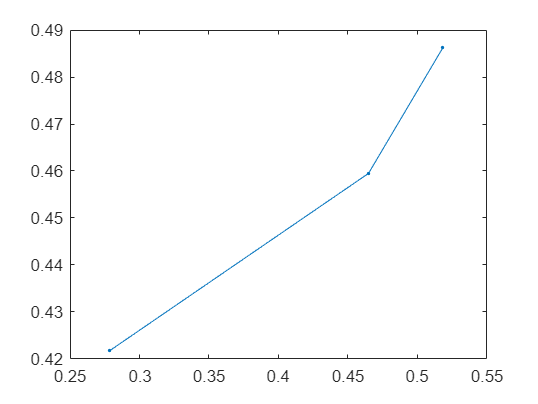

psoparams = struct('popSize',10,...
                     'maxSteps',10, ...
                       'boundaryCond', '', ...
                         'nbrhdSz',3 ...
                  );
rng('default')
psoOut = crcbpso(fitFuncHandle,2,psoparams,2);
%Plot the trajectory of the best particle
figure;
plot(psoOut.allBestLoc(:,1),psoOut.allBestLoc(:,2),'.-');

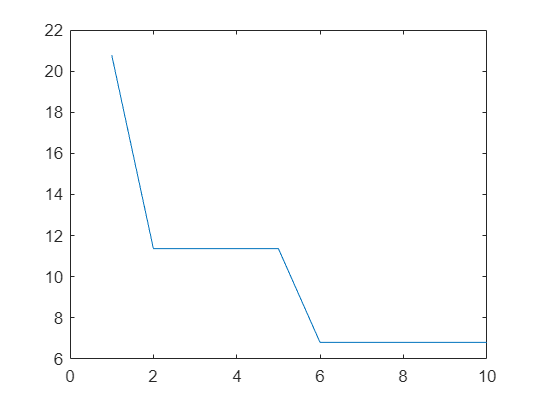

figure;
plot(psoOut.allBestFit);

I also tried this with 100 max steps, each one showing a higher number of steps needed before finding the best fit location.

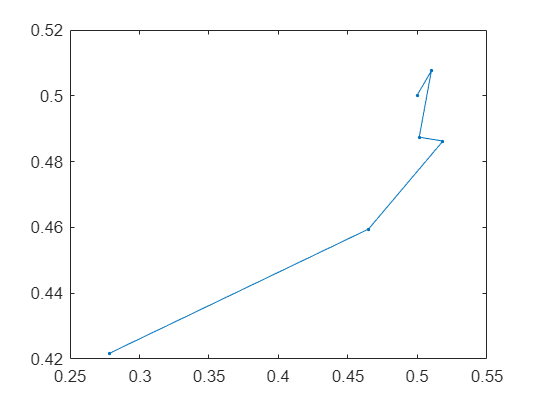

psoparams = struct('popSize',10,...
                     'maxSteps',100,...
                       'boundaryCond', '', ...
                         'nbrhdSz',3 ...
                  );
rng('default')
psoOut = crcbpso(fitFuncHandle,2,psoparams,2);
%Plot the trajectory of the best particle
figure;
plot(psoOut.allBestLoc(:,1),psoOut.allBestLoc(:,2),'.-');

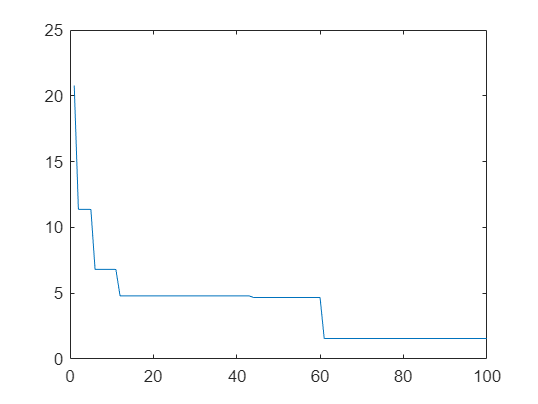

figure;
plot(psoOut.allBestFit);

And again, with 1000 max steps.

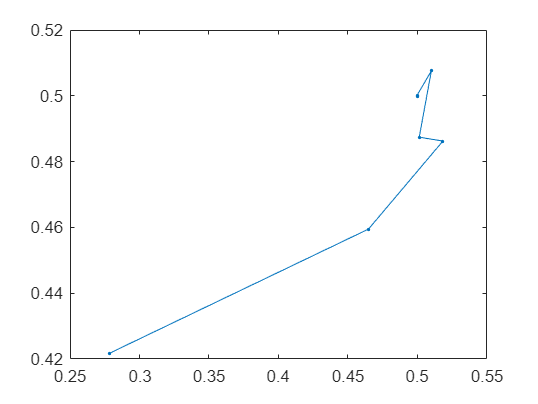

psoparams = struct('popSize',10,...
                     'maxSteps',1000, ...
                       'boundaryCond', '', ...
                         'nbrhdSz',3 ...
                  );
rng('default')
psoOut = crcbpso(fitFuncHandle,2,psoparams,2);
%Plot the trajectory of the best particle
figure;
plot(psoOut.allBestLoc(:,1),psoOut.allBestLoc(:,2),'.-');

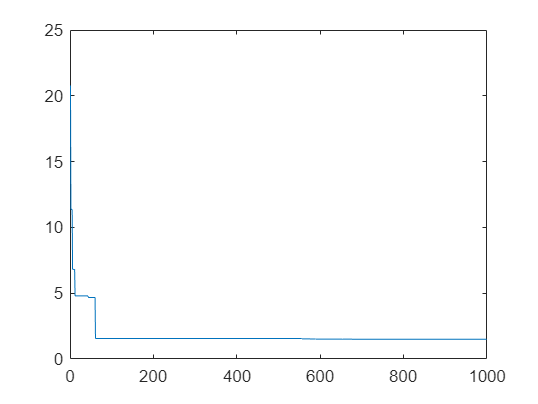

figure;
plot(psoOut.allBestFit);